## eVTOL Multiobjective Design Optimization

Master's Research Project 

Version: v270724

Author: Johannes Janning 

old_name: v2_evtol_pareto_optimization_extended_v220724_v12_star

## Intro

% Clearing the workspace and the command window 
clc
clear

% Importing the model functions
addpath('/Users/johannes/Dropbox/Mein Mac (Johanness MacBook Pro (2))/Documents/MATLAB/Master_Project//MDO_MOO_Model_v2_250724/Model_Functions/Aerodynamics_Model/');
addpath('/Users/johannes/Dropbox/Mein Mac (Johanness MacBook Pro (2))/Documents/MATLAB/Master_Project//MDO_MOO_Model_v2_250724/Model_Functions/PowerMT_Model/');
addpath('/Users/johannes/Dropbox/Mein Mac (Johanness MacBook Pro (2))/Documents/MATLAB/Master_Project//MDO_MOO_Model_v2_250724/Model_Functions/Time_Model/');
addpath('/Users/johannes/Dropbox/Mein Mac (Johanness MacBook Pro (2))/Documents/MATLAB/Master_Project//MDO_MOO_Model_v2_250724/Model_Functions/Energy_Model/');
addpath('/Users/johannes/Dropbox/Mein Mac (Johanness MacBook Pro (2))/Documents/MATLAB/Master_Project//MDO_MOO_Model_v2_250724/Model_Functions/Weight_Model/');
addpath('/Users/johannes/Dropbox/Mein Mac (Johanness MacBook Pro (2))/Documents/MATLAB/Master_Project//MDO_MOO_Model_v2_250724/Model_Functions/Cost_Model/');
addpath('/Users/johannes/Dropbox/Mein Mac (Johanness MacBook Pro (2))/Documents/MATLAB/Master_Project//MDO_MOO_Model_v2_250724/Optimization/');

## Setting fixed simulation paramaters

% Trip distance as separate selectable fixed variable 
set_trip_distance = 50; % km
params = getFixedParameters1(); % FUNCTION calling the fixed paramaters, predefined based on literature research (see model documentation)

## Definition of bounds

% Define the bounds of the optimized design variables
bounds = [500, 5700; % MTOM
          1, 1.5;  % R_cruise
          1, 1.5;  % R_hover
          2, 4;  % c
          9, 20; % b
          100, 400]; %rho_bat

## Initialization of GA for multiobjective Optimization

% GA options using ga for multiobjective
options = optimoptions('gamultiobj', 'PopulationSize', 100, 'Display', 'iter');


% to run the multi-objective GA
[x, fval, exitFlag, output, population, scores] = gamultiobj(@(x)multiObjectiveFunction1(x, params, set_trip_distance), 6, [], [], [], [], bounds(:,1), bounds(:,2), @(x)nonlinearConstraints1(x, params, set_trip_distance), options);


Multi-objective optimization:
6 Variables
4 Nonlinear inequality constraints

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverintermediate
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationadaptfeasible

                              Average            Average
Generation   Func-count    Pareto distance    Pareto spread
    1           101                 1                 1
    2           201           0.19092          0.999979
    3           301         0.0763829          0.999993
    4           401         0.0510911            0.2411
    5           501         0.0438511           0.24636
    6           601         0.0389405          0.251587
    7           701         0.0270767          0.253101
    8           801         0.0251383          0.999988
    9           901         0.0266984           0.24301
   10          1001         0.0155174          0.153432
   11          1101         0.0139312          0.999964
   12          1


% to display results
disp('Optimized Design Variables (x):');

Optimized Design Variables (x):


disp(x);

   1.0e+03 *

    4.7045    0.0015    0.0015    0.0020    0.0155    0.3728
    2.3738    0.0015    0.0015    0.0020    0.0196    0.3805
    4.8819    0.0015    0.0013    0.0020    0.0156    0.3723
    3.4272    0.0015    0.0014    0.0020    0.0155    0.3734
    3.5888    0.0015    0.0015    0.0020    0.0156    0.3753
    2.5669    0.0015    0.0015    0.0020    0.0160    0.3746
    4.5289    0.0015    0.0015    0.0020    0.0155    0.3731
    2.3762    0.0015    0.0015    0.0020    0.0186    0.3774
    2.3809    0.0015    0.0015    0.0020    0.0178    0.3769
    4.8430    0.0015    0.0014    0.0020    0.0156    0.3725
    4.7675    0.0015    0.0014    0.0020    0.0155    0.3731
    3.6826    0.0015    0.0015    0.0020    0.0156    0.3760
    2.3851    0.0015    0.0015    0.0020    0.0175    0.3799
    2.4280    0.0015    0.0015    0.0020    0.0161    0.3761
    2.3873    0.0015    0.0015    0.0020    0.0164    0.3756
    2.6113    0.0015    0.0015    0.0020    0.0156    0.3754
    2.9880

disp('Objective Values:');

Objective Values:


disp(fval);

   1.0e+05 *

    1.4048    0.0077
    0.6521    0.0120
    1.5068    0.0076
    1.0058    0.0089
    1.0504    0.0087
    0.7335    0.0104
    1.3522    0.0078
    0.6582    0.0116
    0.6639    0.0114
    1.4705    0.0076
    1.4534    0.0077
    1.0793    0.0086
    0.6676    0.0112
    0.6904    0.0106
    0.6736    0.0109
    0.7486    0.0101
    0.8679    0.0095
    0.8453    0.0097
    1.0347    0.0089
    0.7176    0.0105
    1.3287    0.0079
    0.6877    0.0108
    0.7068    0.0105
    1.2028    0.0083
    1.1029    0.0086
    0.9139    0.0094
    1.2555    0.0081
    0.7740    0.0100
    1.1746    0.0084
    1.3986    0.0077
    0.8370    0.0097
    0.8873    0.0095
    1.1429    0.0084
    0.6521    0.0120
    0.9831    0.0090



## Post-Processing (MTOM check) & Transportation Mode Comparison Processing

% function to process optimization results for illustration
results = processOptimizationResults1(x, fval, params, set_trip_distance);

## Results and Pareto-Front Displaying


% Defining the names of the objectives, design variables, and calculated values
objectiveNames = {'Trip_Energy', 'Trip_Time'};
designVarNames = {'MTOM', 'R_cruise', 'R_hover', 'chord', 'wingspan_b', 'rho_bat'};
calculatedVarNames = {'V_cruise', 'V_climb', 'Power_Hover', 'Power_Climb', 'Power_Cruise', 'm_empty', 'm_pay', 'm_bat', 'm_motor', 'm_rotor', 'm_wing', 'c_l_cruise', 'c_l_climb', 'toc_s', 'toc', 'coc', 'c_e', 'c_m', 'c_mwr', 'c_mb', 'c_n', 'c_cob', 'coo', 'ioc', 'd_cru', 'd_cl', 'eVTOL_FoM'};

% Creating a table for the results with custom names
resultsTable = array2table(results, 'VariableNames', [objectiveNames, designVarNames, calculatedVarNames]);

% Sorting the table by the first objective function (change the index to sort by a different objective)
sortedResultsTable = sortrows(resultsTable, 'Trip_Energy');

% to display the sorted table
disp('Sorted Results Table:');

Sorted Results Table:


disp(sortedResultsTable);

    Trip_Energy    Trip_Time     MTOM     R_cruise    R_hover    chord     wingspan_b    rho_bat    V_cruise    V_climb    Power_Hover    Power_Climb    Power_Cruise    m_empty    m_pay    m_bat     m_motor    m_rotor    m_wing    c_l_cruise    c_l_climb    toc_s      toc       coc       c_e       c_m      c_mwr      c_mb      c_n      c_cob      coo       ioc      d_cru    d_cl    eVTOL_FoM
    

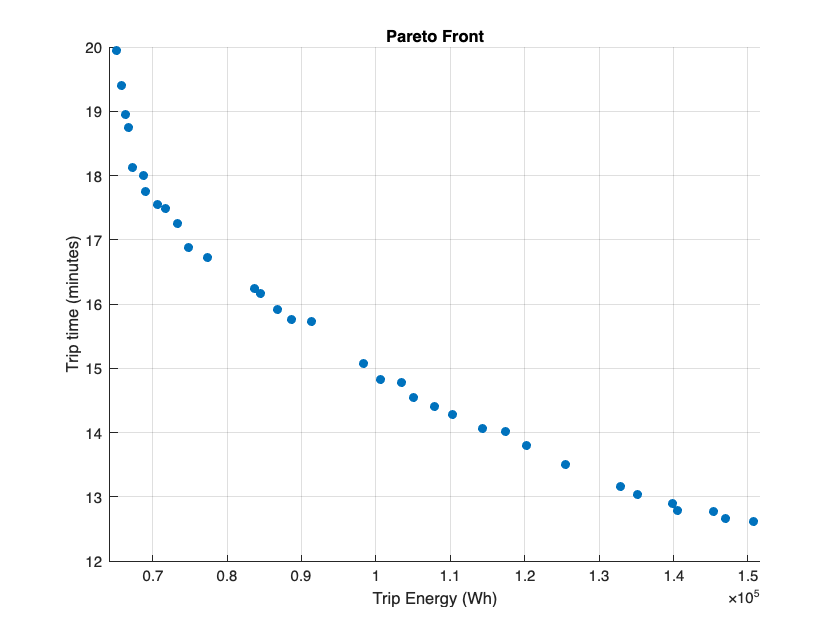


% Plotting the Pareto front
figure;
scatter(fval(:, 1), fval(:, 2) / 60, 'filled');
title('Pareto Front');
xlabel('Trip Energy (Wh)');
ylabel('Trip time (minutes)');
grid on;
xlim([min(fval(:, 1)) - 1000, max(fval(:, 1)) + 1000]);

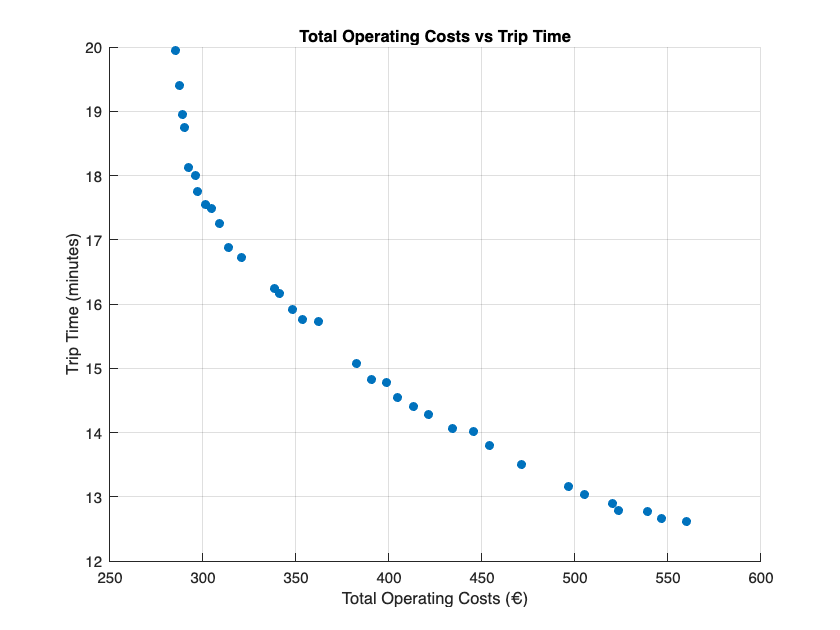


% Ensuring that the 'toc' values are consistent with 'Trip_Energy', to
% prevent table mismatch 
toc_values = sortedResultsTable.toc;
trip_energy = sortedResultsTable.Trip_Energy;
trip_time = sortedResultsTable.Trip_Time;

% Plotting TOC against Trip Time to verify consistency
figure;
scatter( toc_values, trip_time/60, 'filled');
title('Total Operating Costs vs Trip Time');
xlabel('Total Operating Costs (€)');
ylabel('Trip Time (minutes)');
grid on;

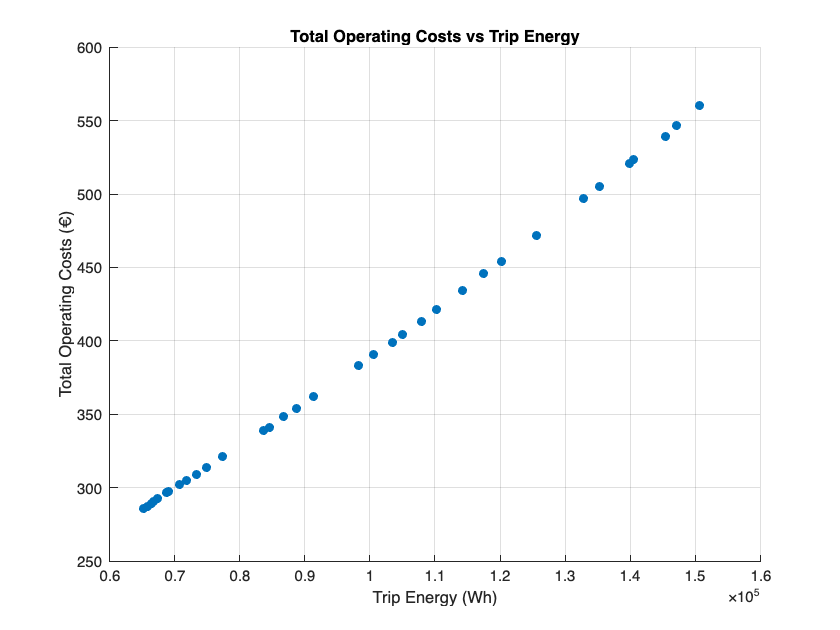


% Plotting TOC against Trip Energy
figure;
scatter(trip_energy, toc_values, 'filled');
title('Total Operating Costs vs Trip Energy');
xlabel('Trip Energy (Wh)');
ylabel('Total Operating Costs (€)');
grid on;


% Saving the table to an Excel file
writetable(sortedResultsTable, 'sorted_results_v2.xlsx');

## Extracting highest eVTOL-FoM for Intermodal Comparison:


% to extract the eVTOL configuration with the maximum FoM
[maxFoM, maxIndex] = max(resultsTable.eVTOL_FoM);
bestConfig = resultsTable(maxIndex, :);

% Calling the function to calculate FoM for all transportation modes
FoM_results = calculateTransportationFoM(bestConfig, params, set_trip_distance);

Intermediate Values in calculateTransportationFoM:
time_rating: 10
co2_rating: 5.7575
energy_rating: 5.6298
costs_rating: 1
FoM: 5.5968



% to display the results
disp(FoM_results);

               Mode                TimeDemand    TimeRating    CO2_total    CO2Rating    EnergyTotal    EnergyRating    CostsTotal    CostsRating     FoM  
    ___________________________    __________    __________    _________    _________    ___________    ____________    __________    ___________    ______

    {'Electric Vehicle (5)'   }          65        7.8003        0.845       9.4182        2245.1          8.2536          1.365        7.1302       8.1506
    {'Train (100%)'           }       73.32         7.394         0.42       9.7108        3421.2          8.0341             12        6.1993       7.8346
    {'Diesel Vehicle (5)'     }    

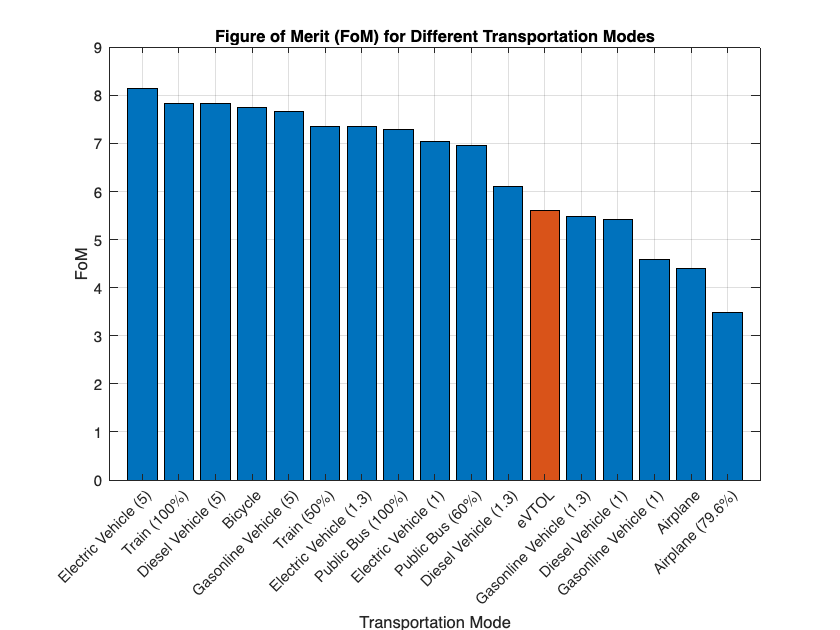


% to ensure the categories are ordered as per the sorted results
mode_categories = categorical(FoM_results.Mode);
mode_categories = reordercats(mode_categories, FoM_results.Mode);

% to identify the index of the eVTOL mode in the sorted results
eVTOL_index = find(FoM_results.Mode == "eVTOL");

% Plotting the results in descending order
figure;
b = bar(mode_categories, FoM_results.FoM);
title('Figure of Merit (FoM) for Different Transportation Modes');
xlabel('Transportation Mode');
ylabel('FoM');
set(gca, 'XTickLabelRotation', 45); % Rotating x-axis labels for better readability
grid on;

% to change the color of the eVTOL bar to orange
b.FaceColor = 'flat';
colors = repmat([0 0.4470 0.7410], length(FoM_results.FoM), 1); % Default blue color for all bars
colors(eVTOL_index, :) = [0.8500 0.3250 0.0980]; % Orange color for eVTOL
b.CData = colors;

## Validation Sequence

% calculate the validation model with best configuration

% Recheck the highest FoM design
validationResults = recheckModel1(bestConfig.rho_bat, bestConfig.MTOM, bestConfig.chord, bestConfig.wingspan_b, bestConfig.V_cruise, bestConfig.V_climb, bestConfig.R_cruise, bestConfig.R_hover, set_trip_distance, params);

% Extract best configuration values
bestConfigValues = struct('Trip_Energy', bestConfig.Trip_Energy, ...
                          'Trip_Time', bestConfig.Trip_Time, ...
                          'V_cruise', bestConfig.V_cruise, ...
                          'V_climb', bestConfig.V_climb, ...
                          'R_cruise', bestConfig.R_cruise, ...
                          'R_hover', bestConfig.R_hover, ...
                          'chord', bestConfig.chord, ...
                          'wingspan_b', bestConfig.wingspan_b, ...
                          'Power_Hover', bestConfig.Power_Hover, ...
                          'Power_Climb', bestConfig.Power_Climb, ...
                          'Power_Cruise', bestConfig.Power_Cruise, ...
                          'MTOM', bestConfig.MTOM, ...
                          'm_empty', bestConfig.m_empty, ...
                          'm_pay', bestConfig.m_pay, ...
                          'm_bat', bestConfig.m_bat, ...
                          'm_motor', bestConfig.m_motor, ...
                          'm_rotor', bestConfig.m_rotor, ...
                          'm_wing', bestConfig.m_wing, ...
                          'c_l_cruise', bestConfig.c_l_cruise, ...
                          'c_l_climb', bestConfig.c_l_climb, ...
                          'toc_s', bestConfig.toc_s, ...
                          'toc', bestConfig.toc, ...
                          'coc', bestConfig.coc, ...
                          'c_e', bestConfig.c_e, ...
                          'c_m', bestConfig.c_m, ...
                          'c_mwr', bestConfig.c_mwr, ...
                          'c_mb', bestConfig.c_mb, ...
                          'c_n', bestConfig.c_n, ...
                          'c_cob', bestConfig.c_cob, ...
                          'coo', bestConfig.coo, ...
                          'ioc', bestConfig.ioc, ...
                          'd_cru', bestConfig.d_cru, ...
                          'd_cl', bestConfig.d_cl);

% Calculate relative differences
fields = fieldnames(bestConfigValues);
relativeDifference = struct();

for i = 1:numel(fields)
    field = fields{i};
    relativeDifference.(field) = round((validationResults.(field) - bestConfigValues.(field)) / bestConfigValues.(field) * 100, 2);
end

% Create the comparison table
comparisonTable = table(struct2array(bestConfigValues)', struct2array(validationResults)', struct2array(relativeDifference)', ...
                        'VariableNames', {'BestConfig', 'Recheck', 'RelativeDifference(%)'}, ...
                        'RowNames', fields);

% Display the comparison table
disp('Comparison Table:');

Comparison Table:


disp(comparisonTable);

                    BestConfig     Recheck      RelativeDifference(%)
                    __________    __________    _____________________

    Trip_Energy          65209         65209              0          
    Trip_Time           1197.3        1197.3              0          
    V_cruise            44.596        44.596              0          
    V_climb             32.562        32.562              0          
    R_cruise               1.5           1.5              0          
    R_hover             1.4977        1.4977              0          
    chord               2.0242        2.0242              0          
    wingspan_b          19.555        19.555              0          
    Power_Hover     4.7998e+05    4.7998e+05


constraint_cruise = bestConfig.MTOM * params.g - params.rho/2 * bestConfig.V_cruise^2 * bestConfig.chord * bestConfig.wingspan_b * bestConfig.c_l_cruise;
cruise_requirement = sqrt( bestConfig.MTOM * params.g * 2 / (params.rho * bestConfig.chord * bestConfig.wingspan_b * bestConfig.c_l_cruise));
climb_requirement = sqrt(cosd(params.alpha_deg_climb)* bestConfig.MTOM * params.g *2 /(params.rho_climb*bestConfig.c_l_climb*bestConfig.chord*bestConfig.wingspan_b));

disp('Cruise Condition Check:');

Cruise Condition Check:


disp(constraint_cruise);

     0




disp('Cruise Speed Required:');

Cruise Speed Required:


disp(cruise_requirement);

   44.5964




disp('Climb Speed Required:');

Climb Speed Required:


disp(climb_requirement);

   32.1654





disp('(1) MTOM Penalty:');

(1) MTOM Penalty:


disp(constraint_cruise/9.81);

     0




disp('(2) Cruise Speed Penalty:');

(2) Cruise Speed Penalty:


disp(climb_requirement- bestConfig.V_climb);

   -0.3962




disp('(3) Climb Speed Penalty:');

(3) Climb Speed Penalty:


disp(cruise_requirement - bestConfig.V_cruise);

  -7.1054e-15





% compare values in total as well relative in a table

% idea: recirculat the whole optimization until the validation discrepancy
% is wihtin a defined margin 



% Fastest Solution:

% to extract the eVTOL configuration with the minimum FoM
[minFoM, minIndex] = min(resultsTable.eVTOL_FoM);
worstConfig = resultsTable(minIndex, :);

% Calling the function to calculate FoM for all transportation modes
FoM_results_worst = calculateTransportationFoM(worstConfig, params, set_trip_distance);

Intermediate Values in calculateTransportationFoM:
time_rating: 10
co2_rating: 1
energy_rating: 1.6412
costs_rating: 1
FoM: 3.4103



% to display the results
disp(FoM_results_worst);

               Mode                TimeDemand    TimeRating    CO2_total    CO2Rating    EnergyTotal    EnergyRating    CostsTotal    CostsRating     FoM  
    ___________________________    __________    __________    _________    _________    ___________    ____________    __________    ___________    ______

    {'Electric Vehicle (5)'   }          65          7.54        0.845       9.4659        2245.1          8.2536          1.365        8.2787       8.3846
    {'Train (100%)'           }       73.32        7.1493         0.42       9.7345        3421.2          8.0341             12        7.7204       8.1596
    {'Diesel Vehicle (5)'     }    

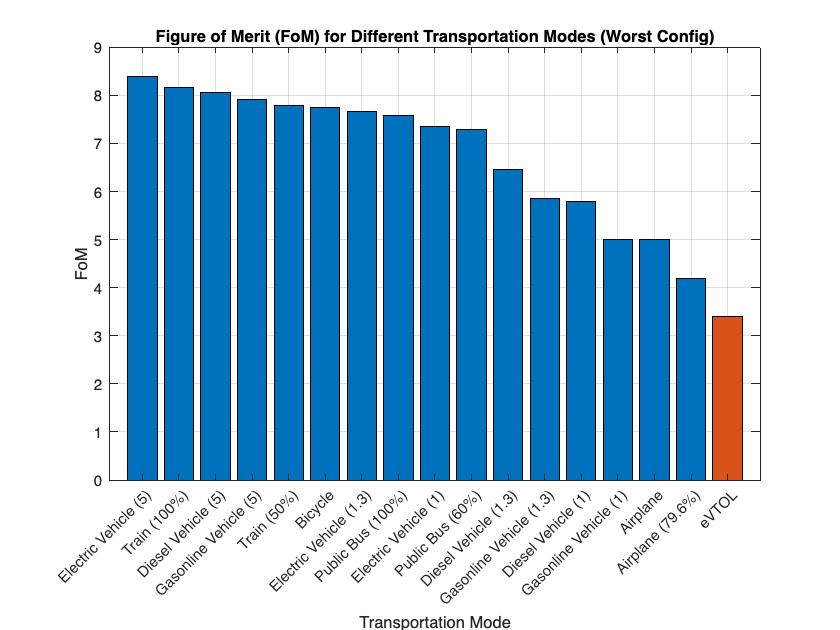


% to ensure the categories are ordered as per the sorted results
mode_categories_worst = categorical(FoM_results_worst.Mode);
mode_categories_worst = reordercats(mode_categories_worst, FoM_results_worst.Mode);

% to identify the index of the eVTOL mode in the sorted results
eVTOL_index_worst = find(FoM_results_worst.Mode == "eVTOL");

% Plotting the results in descending order
figure;
b_worst = bar(mode_categories_worst, FoM_results_worst.FoM);
title('Figure of Merit (FoM) for Different Transportation Modes (Worst Config)');
xlabel('Transportation Mode');
ylabel('FoM');
set(gca, 'XTickLabelRotation', 45); % Rotating x-axis labels for better readability
grid on;

% to change the color of the eVTOL bar to orange
b_worst.FaceColor = 'flat';
colors_worst = repmat([0 0.4470 0.7410], length(FoM_results_worst.FoM), 1); % Default blue color for all bars
colors_worst(eVTOL_index_worst, :) = [0.8500 0.3250 0.0980]; % Orange color for eVTOL
b_worst.CData = colors_worst;



% Recheck the worst FoM design
validationResultsWorst = recheckModel1(worstConfig.rho_bat, worstConfig.MTOM, worstConfig.chord, worstConfig.wingspan_b, worstConfig.V_cruise, worstConfig.V_climb, worstConfig.R_cruise, worstConfig.R_hover, set_trip_distance, params);

% Extract worst configuration values
worstConfigValues = struct('Trip_Energy', worstConfig.Trip_Energy, ...
                           'Trip_Time', worstConfig.Trip_Time, ...
                           'V_cruise', worstConfig.V_cruise, ...
                           'V_climb', worstConfig.V_climb, ...
                           'R_cruise', worstConfig.R_cruise, ...
                           'R_hover', worstConfig.R_hover, ...
                           'chord', worstConfig.chord, ...
                           'wingspan_b', worstConfig.wingspan_b, ...
                           'Power_Hover', worstConfig.Power_Hover, ...
                           'Power_Climb', worstConfig.Power_Climb, ...
                           'Power_Cruise', worstConfig.Power_Cruise, ...
                           'MTOM', worstConfig.MTOM, ...
                           'm_empty', worstConfig.m_empty, ...
                           'm_pay', worstConfig.m_pay, ...
                           'm_bat', worstConfig.m_bat, ...
                           'm_motor', worstConfig.m_motor, ...
                           'm_rotor', worstConfig.m_rotor, ...
                           'm_wing', worstConfig.m_wing, ...
                           'c_l_cruise', worstConfig.c_l_cruise, ...
                           'c_l_climb', worstConfig.c_l_climb, ...
                           'toc_s', worstConfig.toc_s, ...
                           'toc', worstConfig.toc, ...
                           'coc', worstConfig.coc, ...
                           'c_e', worstConfig.c_e, ...
                           'c_m', worstConfig.c_m, ...
                           'c_mwr', worstConfig.c_mwr, ...
                           'c_mb', worstConfig.c_mb, ...
                           'c_n', worstConfig.c_n, ...
                           'c_cob', worstConfig.c_cob, ...
                           'coo', worstConfig.coo, ...
                           'ioc', worstConfig.ioc, ...
                           'd_cru', worstConfig.d_cru, ...
                           'd_cl', worstConfig.d_cl);


% Calculate relative differences for the worst configuration
relativeDifferenceWorst = struct();

for i = 1:numel(fields)
    field = fields{i};
    relativeDifferenceWorst.(field) = round((validationResultsWorst.(field) - worstConfigValues.(field)) / worstConfigValues.(field) * 100, 2);
end

% Create the comparison table for the worst configuration
comparisonTableWorst = table(struct2array(worstConfigValues)', struct2array(validationResultsWorst)', struct2array(relativeDifferenceWorst)', ...
                             'VariableNames', {'WorstConfig', 'Recheck', 'RelativeDifference(%)'}, ...
                             'RowNames', fields);

% Display the comparison table for the worst configuration
disp('Comparison Table (Worst Config):');

Comparison Table (Worst Config):


disp(comparisonTableWorst);

                    WorstConfig     Recheck      RelativeDifference(%)
                    ___________    __________    _____________________

    Trip_Energy     1.5068e+05     1.5068e+05              0          
    Trip_Time           757.21         757.21              0          
    V_cruise            72.727         72.727              0          
    V_climb             53.402         53.402              0          
    R_cruise            1.4733         1.4733              0          
    R_hover             1.2776         1.2776              0          
    chord               2.0188         2.0188              0          
    wingspan_b          15.566         15.566              0          
    Power_Hover     1.6594e+06    


constraint_cruise_worst = worstConfig.MTOM * params.g - params.rho/2 * worstConfig.V_cruise^2 * worstConfig.chord * worstConfig.wingspan_b * worstConfig.c_l_cruise;
cruise_requirement_worst = sqrt(worstConfig.MTOM * params.g * 2 / (params.rho * worstConfig.chord * worstConfig.wingspan_b * worstConfig.c_l_cruise));
climb_requirement_worst = sqrt(cosd(params.alpha_deg_climb) * worstConfig.MTOM * params.g * 2 / (params.rho_climb * worstConfig.c_l_climb * worstConfig.chord * worstConfig.wingspan_b));

disp('Cruise Condition Check (Worst Config):');

Cruise Condition Check (Worst Config):


disp(constraint_cruise_worst);

  -1.4552e-11




disp('Cruise Speed Required (Worst Config):');

Cruise Speed Required (Worst Config):


disp(cruise_requirement_worst);

   72.7267




disp('Climb Speed Required (Worst Config):');

Climb Speed Required (Worst Config):


disp(climb_requirement_worst);

   52.7519




disp('(1) MTOM Penalty (Worst Config):');

(1) MTOM Penalty (Worst Config):


disp(constraint_cruise_worst / 9.81);

  -1.4834e-12




disp('(2) Cruise Speed Penalty (Worst Config):');

(2) Cruise Speed Penalty (Worst Config):


disp(climb_requirement_worst - worstConfig.V_climb);

   -0.6497




disp('(3) Climb Speed Penalty (Worst Config):');

(3) Climb Speed Penalty (Worst Config):


disp(cruise_requirement_worst - worstConfig.V_cruise);

     0



Drawing the eVTOL Configruation (against the baseline configuration)

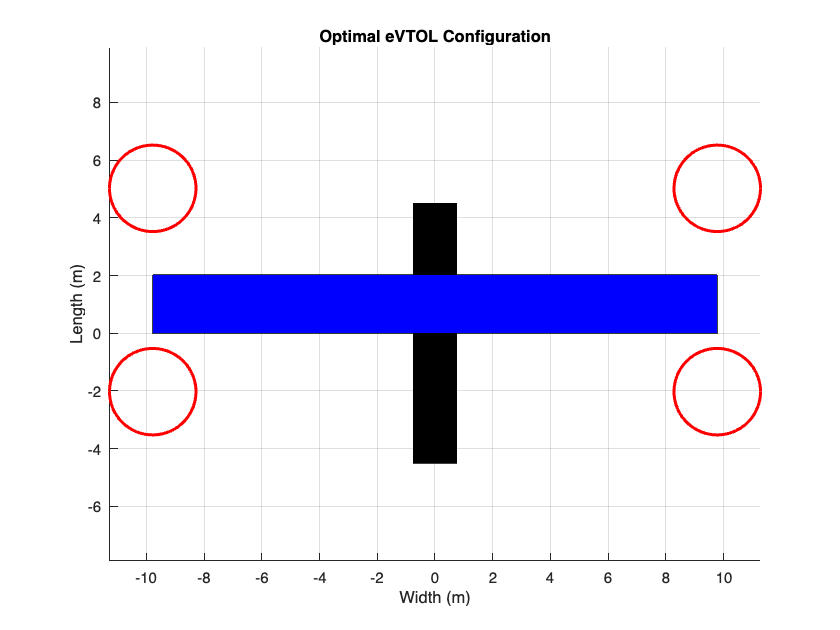

% Under construction 

% Extract the optimal parameters from the best configuration
bestConfig = sortedResultsTable(1, :);

R_prop_hover = bestConfig.R_hover;
R_prop_cruise = bestConfig.R_cruise;
wingspan = bestConfig.wingspan_b;
chord = bestConfig.chord;

% Call the function to draw the eVTOL
drawEVTOL(R_prop_hover, R_prop_cruise, wingspan, chord, 'Optimal eVTOL Configuration');